# Problem 4

## (a)

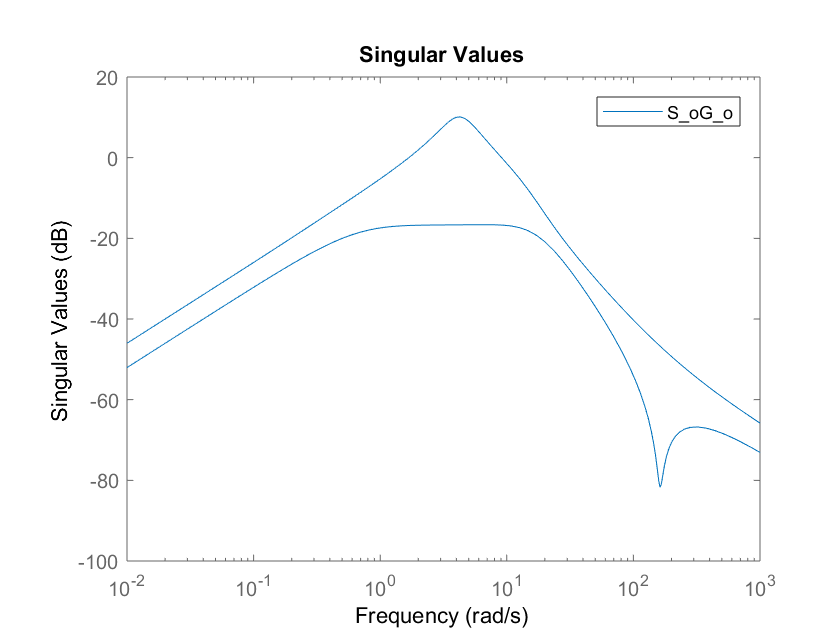

clear all; 
close all; 
clc; 

sys11 = tf([ 0 0 6],[0.09 1 1]);
sys12 = tf([0 -0.05],[0.1 1]);
sys21 = tf([0 0.07],[0.3 1]);
sys22 = tf([0 0 5],[0.108 1.74 -1]);

G0 = [sys11, sys12; 
       sys21, sys22]; 

K11 = tf([2 2],[1 0]);
K12 = tf([-1 0],[3 1]);
K21 = tf([-5 -5],[0.8 1]);
K22 = tf([4*0.7 4],[1 0]);

K = [K11,K12; 
     K21 K22];

loops = loopsens(G0,K);

% 4.1.i input di to y 
figure
sigma(loops.So*G0)
legend('S_oG_o')
hold on 

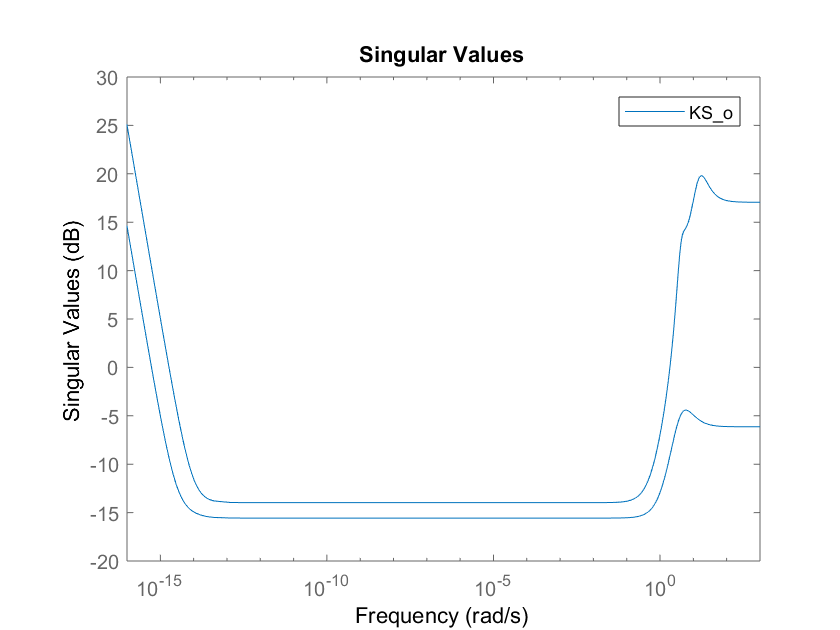


% u --> r 
figure 
sigma(K*loops.So)
legend('KS_o')
hold on 

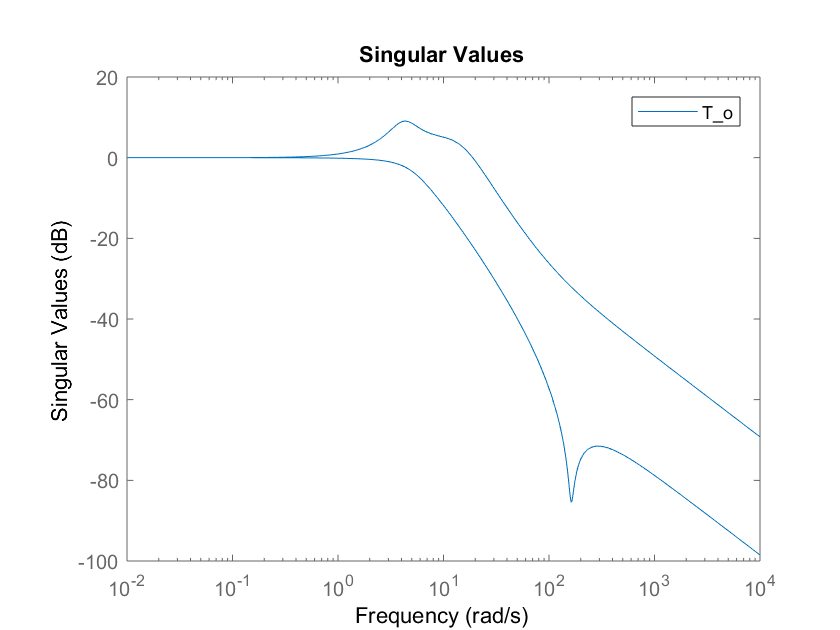


% n --> y small max(svd(T_o)
figure 
sigma(loops.To)
legend('T_o')
hold on

## 4(b)

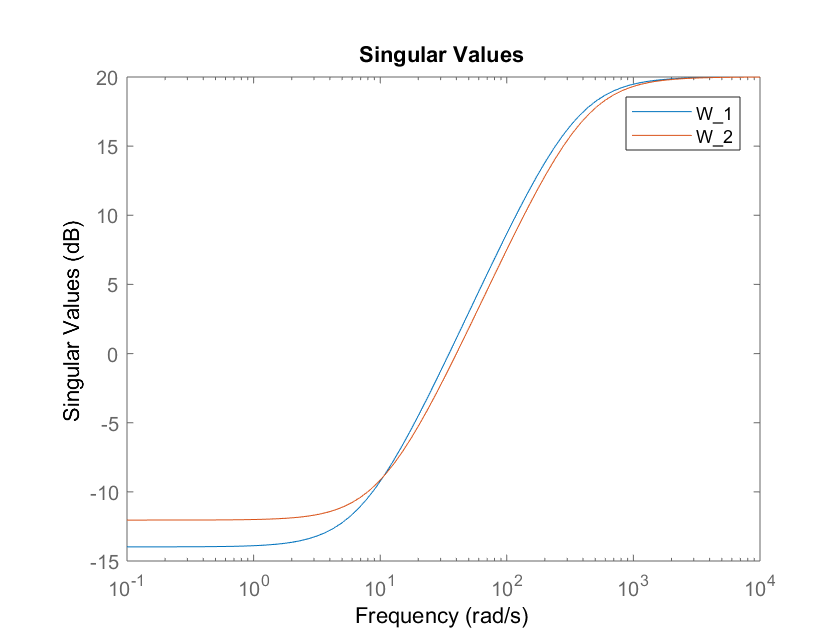

W1 = makeweight(0.20,35,10);
W2 = makeweight(0.25,40,10);

figure
sigma(W1)
hold on 
sigma(W2)
legend('W_1', 'W_2')
hold on

## 4(c)

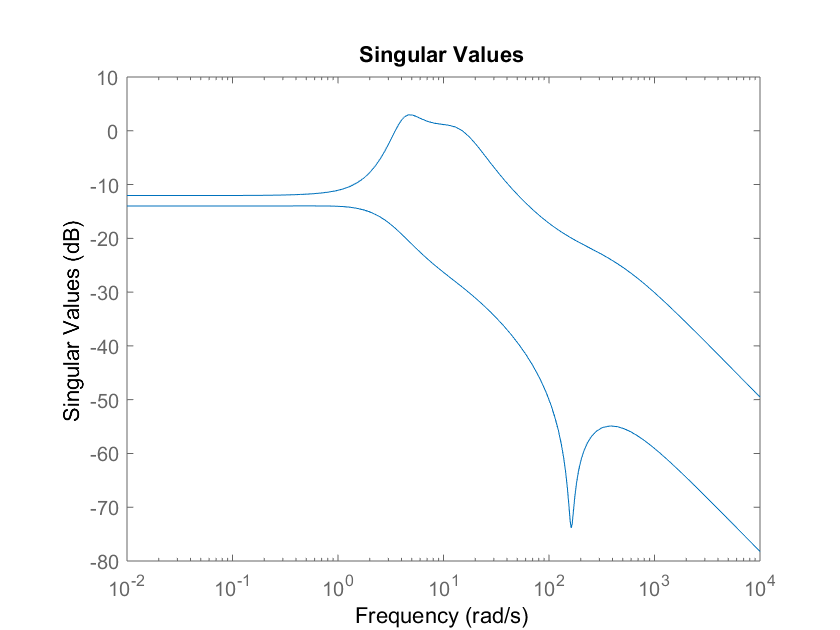

WI = [W1, 0; 0,W2];
M = -WI*loops.Ti; 

figure 
sigma(M)


HinfNorm1 = hinfnorm(M)

HinfNorm1 = 1.4104

if HinfNorm1 > 1.0 
    fprintf('Controller is not robust')
else 
    fprintf('System is robutst')
end

Controller is not robust

## 4(c) Part b

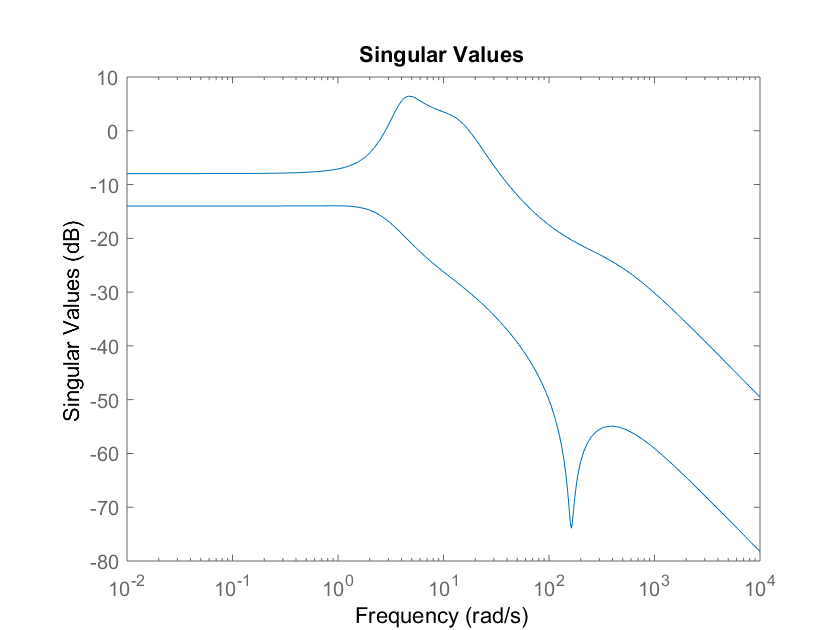

W2New = makeweight(0.40,40,10);
WId = [W1, 0; 0,W2New];
M = -WId*loops.Ti; 

figure 
sigma(M)

HinfNorm2 = hinfnorm(M)

HinfNorm2 = 2.1031


if HinfNorm2 > 1.0 
    fprintf('Controller is not robust')
else 
    fprintf('System is robutst')
end

Controller is not robust

## 4(d)

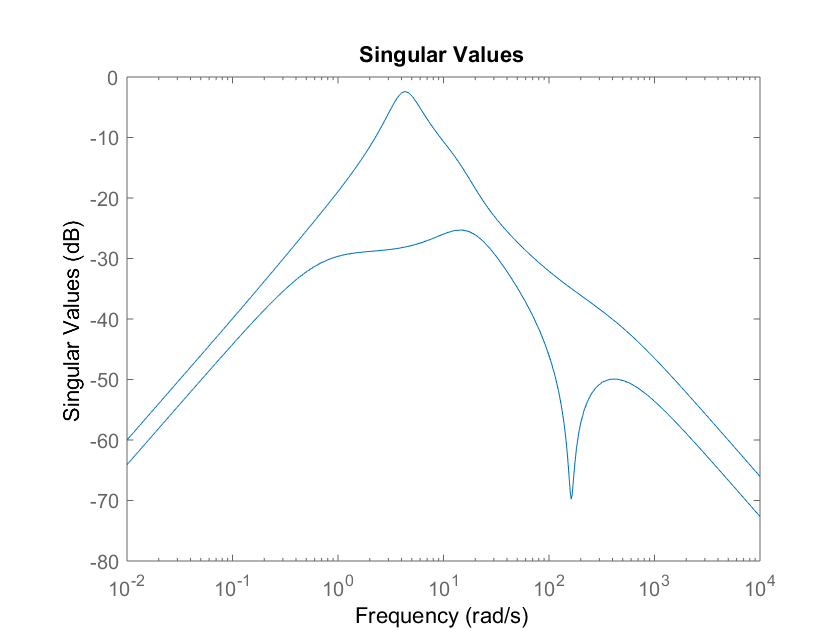

M_d = loops.PSi*WI;

figure 
sigma(M_d)

HinfNormM_d = hinfnorm(M_d)

HinfNormM_d = 0.7579


if HinfNormM_d > 1.0 
    fprintf('Controller is not robust')
else 
    fprintf('System is robutst')
end

System is robutst